numG = [0.25];
denG = [1, 0.4, 0.25];
G = tf(numG, denG);



Kp = 10;  
Kd = 59.5;

numC = [Kd, Kp];
denC = [1];
C = tf(numC, denC)


C =
 
  59.5 s + 10
 
Continuous-time transfer function.
Model Properties


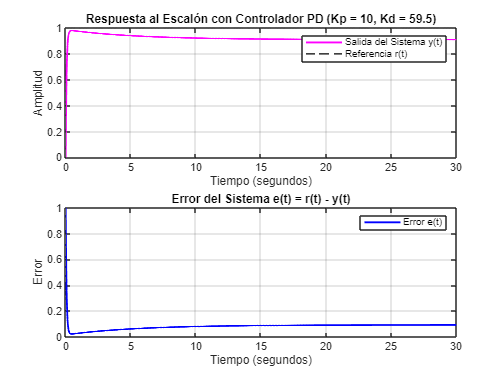


T = feedback(C * G, 1);

t = 0:0.01:30;
[y, ~] = step(T, t);

r = ones(size(y)); 

error = r - y;
figure(2); 
subplot(2, 1, 1); 
plot(t, y, 'm-', 'LineWidth', 1.5);
hold on;
plot(t, r, 'k--', 'LineWidth', 1); 
grid on;
title(['Respuesta al Escalón con Controlador PD (Kp = ', num2str(Kp), ', Kd = ', num2str(Kd), ')']);
ylabel('Amplitud');
xlabel('Tiempo (segundos)');
legend('Salida del Sistema y(t)', 'Referencia r(t)');

subplot(2, 1, 2); 
plot(t, error, 'b-', 'LineWidth', 1.5);
grid on;
title('Error del Sistema e(t) = r(t) - y(t)');
ylabel('Error');
xlabel('Tiempo (segundos)');
legend('Error e(t)');
hold on



disp('Función de transferencia del controlador PD C(s):')

Función de transferencia del controlador PD C(s):


C


C =
 
  59.5 s + 10
 
Continuous-time transfer function.
Model Properties


disp('Función de transferencia del sistema controlado T(s):')

Función de transferencia del sistema controlado T(s):


T


T =
 
     14.88 s + 2.5
  --------------------
  s^2 + 15.28 s + 2.75
 
Continuous-time transfer function.
Model Properties


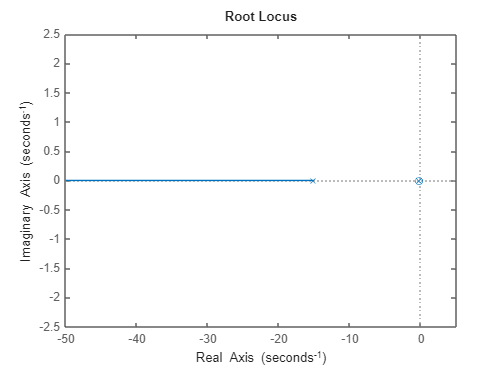

figure;
rlocus(T)